# 03 Exchange Data with ROS Publishers and Subscribers

This example shows how to publish and subscribe to topics in a ROS network.

The primary mechanism for ROS nodes to exchange data is sending and receiving *messages*. Messages are transmitted on a *topic,* and each topic has a unique name in the ROS network. If a node wants to share information, it uses a *publisher* to send data to a topic. A node that wants to receive that information uses a *subscriber* to that same topic. Besides its unique name, each topic also has a *message type*, which determines the types of messages that are capable of being transmitted under that topic.

This publisher and subscriber communication has the following characteristics:      

- Topics are used for many-to-many communication. Many publishers can send messages to the same topic and many subscribers can receive them.

- Publishers and subscribers are decoupled through topics and can be created and destroyed in any order. A message can be published to a topic even if there are no active subscribers.

The concept of topics, publishers, and subscribers is illustrated in the figure:

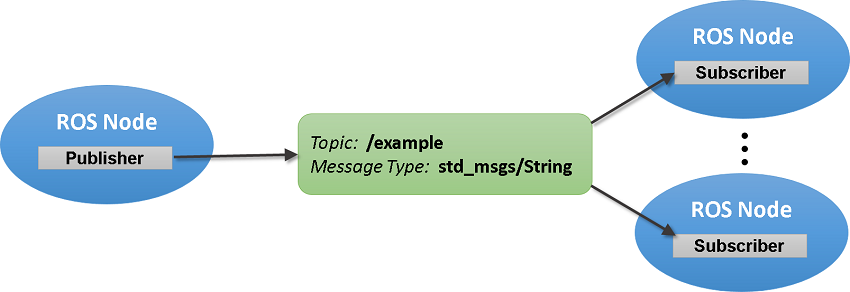

Besides how to publish and subscribe to topics in a ROS network, this example also shows how to:

- Wait until a new message is received

- Use callbacks to process new messages in the background

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a),  [Connect to a ROS Network](docid:ros_ug.mw_d625a603-7f37-4925-9470-2de734937434)

## Subscribe and Wait for Messages

Start the ROS master in MATLAB® using the [`rosinit`](docid:ros_ref.bupf5_j_1) command.

rosinit

Create a sample ROS network with several publishers and subscribers using the provided helper function `exampleHelperROSCreateSampleNetwork`.

exampleHelperROSCreateSampleNetwork

Use [`rostopic`](docid:ros_ref.bupf5_j_14)` list` to see which topics are available.

rostopic list

**Pose Topic**

To verify that the publisher objects are actually publishing at a rate of 10Hz, we can listen on these two topics. We will do so 1 by 1. 

rostopic echo /pose

To stop listent: press ctrl+c

**Scan Topic**

To verify that the publisher objects are actually publishing at a rate of 10Hz, we can listen on these two topics. We will do so 1 by 1. 

rostopic echo /scan

To stop listent: press ctrl+c

#### Which nodes publish them?

Use `rostopic info` to check if any nodes are publishing to the `/scan` topic. The command below shows that `node_3` is publishing to it.

rostopic info /pose % published by node_1
rostopic info /scan % published by node_3

### **Getting Published Information**

Published information is accessible via** subscriber objects. **

In** exampleHelperROSCreateSampleNetwork **we created 2 subscriber objects: (i) twistSub and (ii) scanSub. 

We will learn 3 ways of accessible information:

- Via subscriber object -- immediate response (non-blocking)

- Via `receive` -- only returns when data exists (blocking)

- Callback functions

**01 Get Data via Subscriber Object (Non-Blocking)**

By simply calling an existing subscriber object, you will access the latest message flowing on the prescribed topic.

If no data is flowing in the topic, the 

To retrieve the data, call the subcriber object. 

msg = twistSub

The object is a structure with several fields including:

`    TopicName: `

`    LatestMessage: `

`    MessageType: `

`    BufferSize: `

`    NewMessageFcn: []`

`    DataFormat: 'struct'`

`To get the actual data, access the LatestMessage field (may get another structure):`

twistSub.LatestMessage % or msg.LatestMessage

It's a strcutre, so  you need to continue to drill down:

twistSub.LatestMessage.Linear   % or msg.LatestMessage.Linear
twistSub.LatestMessage.Angular  % or msg.LatestMessage.Angular

Notice that when you call the same object again, you should be getting updated information:

twistSub.LatestMessage.Linear   % or msg.LatestMessage.Linear
twistSub.LatestMessage.Angular  % or msg.LatestMessage.Angular

### 02 Via receive -- only returns when data exists (Blocking)

Another way of getting information is via the ros toolbox function '**receive(ros.Subscriber)**'.

This method takes in a ros.subscriber object. We can for example receive data from both the /pose topic and the /scan topic via those subscriber objects as well:

msgPose = receive(twistSub)

msgScan = receive(scanSub1)

**Visualization**

Some message types have visualizers associated with them. 

For the LaserScan message, `rosplot` plots the scan data. The `MaximumRange` name-value pair specifies the maximum plot range.

figure
rosPlot(msgScan,"MaximumRange",7)

#### Blocking part

Sometimes, we may not want our code to continue until we guarantee that a message is received. To this end, we will use the `receive(ros.Subscriber)` method. 

When a program has to wait until an event happens before continuing to run, that is called a blocking call. 

We can demonstrate this by creating a publisher object onto a new topic but not send any information on it for some time (we can use the pause method) . 

fooPub = ros.Publisher(node_3, '/fooTopic', 'std_msgs/String', 'DataFormat', "struct");    % 1 Create a publisher object
fooPubMsg = rosmessage(fooPub);                                                            % 2 Create a publisher message
fooPubMsg.Data = 'this delayed message showed up only when it is published'                % 3 Populate the message

fooSub = ros.Subscriber(node_3, "/fooTopic", "std_msgs/String", "DataFormat", "struct");  % 4 Also create subscriber

Now we will publish the message with a 5 second delay with a non-blocking asyncronous command. 

Run the next two commands back to back quickly. 

start( timer('TimerFcn', @(myTimerObj, thisEvent) send(fooPub, fooPubMsg), 'StartDelay', 10)) % 5 Will send the fooPubmsg message via the fooPubmsg publisher object in 5 secs, but receive() will execute immediately

msg = receive(fooSub)                                                                        % 6 ask the subscriber to receive, 
msg.Data
1+1                                                                                          % the code will not run any subsequent lines of code until it receives data and stops blocking

### 03 Subscribe Using Callback Functions

Finally, instead of calling the ros.Subscriber object to get information once or using [`receive`](docid:ros_ref.buqbyro) to get blocking data, we have a third way to get data over and over as new messages are received. 

Receiving data (images, joint values, forces) may occur in the order of 10s, 100s, or even 1000s of messages per second. Callbacks offer us a convenient way of updating our variables at the same rate as data comes in. 

More specifically, a callback is a function that will get called as a separate thread/program. You can create global variables in that function, that you can then use in other scripts to use that data. 

Three steps are to be taken:

- Create a `ros.Subsriber` object and provide the name of the callback function to be called starting with the '@' sign:

- Create a callback function that has two input arguments (~,message). Access the message structure and save data to global variables.

- Access data via global variables. Variables need to be declared as global BOTH in the callback and here with the same names. Then we can use them here to achieve goals like control. Our global variables will be " pos" and "orient". 

Create a ros subcriber object with a callback:

pos_orient_sub = ros.Subscriber(node_3, ...                         $ Node that will subscribe
                                "/pose", ...                        % Topic from which you will get the data
                                @exampleHelperROSPoseCallback, ...  % Callback. Always starts with @ will set data to global variables 
                                "DataFormat","struct");               

Define two global variables `pos` and `orient`.

global pos
global orient

Now you can use the global variables to achieve purposes.

Call them a couple of times to see them update:

pos
orient
pos
orient

You could use these values to task your robot to move to those poses. 

Let's bring some commands from our previous lessons. 

Below I will:

- Create a robot

- Create Numerical IKs

- Create a loop to receive new pos/orient

- Convert to a pose

- Convert pose to joint angles

- Display robot at new angles

Later you will learn to move the robot via ROS.

rate = rateControl(10); % Update at 10 Hz

% Load the robot 
ur = loadrobot("universalUR5e", 'DataFormat','row');

% Create inverse kinematics numerical object
ik = inverseKinematics(RigidBodyTree=ur);

for i = 1:20 % We will only sample 10 points

    % Print loop iteration
    fprintf("Loop # %d", i);
    
    % Create a pose from position and rpy orientation using peter corke's rpy2tr
    T = transl(pos)*rpy2tr(orient)
    
    % Compute joint angles via numerical IKs
    [q,solinfo] = ik("tool0",T,ones(1,6),ur.homeConfiguration);

    % Display the 1st solution if it exists
    [r,c] = size(q)
    if r>0
        ur.show( q(1,:),FastUpdate=true,PreservePlot=false);
    end
    
    rate.waitfor;
end


Stop the pose subscriber by clearing the subscriber variable

clear pos_orient_sub

*Note*: 

- There are other ways to extract information from callback functions besides using globals. 

- For example, you can pass a *handle object* as additional argument to the callback function. 

- See the [Callback Definition](docid:creating_plots.bt_h1z8) documentation for more information about defining callback functions.

## Publish Messages

Create a publisher that sends ROS string messages to the `/chatter` topic (see [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36)).

Note:

- If you create a publisher, you can choose the topic name. It is entirely up to you. 

- If you are connecting to an existing network, it is important you are familiar with the topic names. 

chatterpub = rospublisher("/chatter", ...           % We will publish to this topic 
                          "std_msgs/String", ...    % This is the type of the message. 
                          "DataFormat","struct")
pause(2) % Wait to ensure publisher is registered

**Verify Newly Created Topic**

Use `rostopic list` to verify that the `/chatter` topic is available in the ROS network.

rostopic list

#### Message Types

Get familiar with the message types in ROS via the rosmsg show command:

rosmsg show std_msgs/String

Which outputs:

>> char Data

#### Populating the Message

To populate such message, we need to first create a message object of type std_msgs/String.

We can do that via the `rosmessage` command.

The rossmessage command can take two kinds of input:

- A string with the ros message type, i.e. 'std_msgs/String'

- A publisher object who has already been attributed a topic name and message type (as we did in L19-21):

chattermsg = rosmessage(chatterpub); 
% Alternatively you could also do: cattermsg = rosmessage('std_msgs/String')

After creating the message, you will want to fill it with relevant information before sending the data out to the robot network. 

Normally this would be goal information for the robot. Here we will do a simple string.

Note:

- chattermsg is a structure not a variable. 

- We want to set our goal string not to chattermsg itself, but to the relevant entry in the structure. In this case it is `chattermsg.Data:`

chattermsg.Data = 'hello world'

#### Creating a Subscriber

Define a subscriber for the `/chatter` topic.  

`exampleHelperROSChatterCallback` is called when a new message is received and displays the string content in the message (do edit `exampleHelperROSChatterCallback) to see how it is called.`

chattersub = rossubscriber("/chatter", ...
                           @exampleHelperROSChatterCallback, ...
                           "DataFormat","struct")

#### Publish and Receive

In the next line, we will pubslih the `chattermsg` message to the `/chatter` topic via the `send` command. 

As soon as we do that, the message will be *caught* by the subscriber callback function we just created called: @exampleHelperROSChatterCallback.

As it catches that message, it will execute it's code (do 'edit exampleHelperROSChatterCallback') and display the string that has been published.

send(chatterpub,chattermsg)
pause(2)

#### Play with it

Change the  published msg value, publish it, and see the callback again:

chattermsg.Data = 'this is a new string'
send(chatterpub,chattermsg)

## Shut Down ROS Network

Remove the sample nodes, publishers, and subscribers from the ROS network one by one via the `clear('object')` command as seen in (edit exampleHelperROSShutDownSampleNetwork):

Clear the global variables `pos` and `orient.`

exampleHelperROSShutDownSampleNetwork
clear global pos orient

Shut down the ROS master and delete the global node.

rosshutdown

## Next Steps

- To learn more about how ROS messages are handled in MATLAB, see [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36) and [Work with Specialized ROS Messages](docid:ros_ug.mw_f993bbbe-25de-434f-bfd0-e5243256b23c).

- To explore ROS services, refer to [Call and Provide ROS S    ervices](docid:ros_ug.mw_70dbf089-5821-4e67-b96f-f659aea10c0c).

*Copyright 2014-2021 The MathWorks, Inc.*